# Weights and Balances

clear all; close all; clc;

## Initialization

#### Design Variables

Aerodynamics

%Main Wing
    S = 0.2413;
    b = 1.042;
    c = 0.2316;
    S_wet = 0.502191;
%Horizontal Tail
    S_HT = 0.1; %horizontal tail area [CHANGE]
    c_HT = 0.1; %horizontal tail chord [CHANGE]
    b_HT = 0.4; %horizontal tail span [CHANGE]
%Vertical Tail
    S_VT = 0.1; %vertical tail area [CHANGE]
    c_VT = 0.1; %vertical tail chord [CHANGE]
    b_VT = 0.4; %vertical tail span [CHANGE]

Payload

rho_P2 = 2; %package 2 cardboard density [kg/m^3]
V_P2 = 0.001; %package 2 cardboard volume [m^3]

#### Target Stability

SM_target = 10; %Static Margin Target

## Loop Initialization

Initial Guesses

AL = 2; %aircraft length [m]
L_MW = 0.3; %location of leading edge of main wing from front
L_TW = 0.8; %location of leading edge of tail wings from front
L_HT = 1; %distance from MW 1/4 chord to HT 1/4 chord
L_VT = 1; %distance from MW 1/4 chord to HT 1/4 chord
L_F = 0.1; %distance from front to start of fuselage

## Center of Gravity

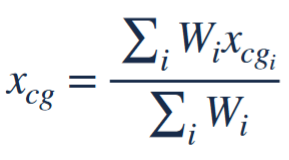

#### Wing CG

    Wing Weight:

m_MW = 2; %main wing mass [kg]
m_HT = 2; %horizontal tail mass [kg]
m_VT = 2; %vertical tail mass [kg]

    Local CG

CG_L_MW = 0.25; %local center of gravity (main wing)
CG_L_HT = 0.25; %local center of gravity (horizontal tail)
CG_L_VT = 0.25; %local center of gravity (vertical tail)

    Global CG

CG_G_MW = L_MW*AL + CG_L_MW*c; %global main wing CG
CG_G_HT = CG_G_MW + L_HT;
CG_G_VT = CG_G_MW + L_VT;

#### Fuselage CG

    Fuselage Weight

m_F = 2; %fuselage mass [kg]

    Local:

CG_L_F = 0.5; %local fuselage CG

    Global:

FL = 0.5; %fuselage length [m]
CG_G_F = L_F + CG_L_F*FL;

#### Components

    Component Weights

m_Motor = 0.0730; %motor mass [kg]
m_SC = 0.051; %speed controller mass [kg]
m_Bat = 0.156; %battery mass [kg]
m_Rec = 0.0166; %receiver mass [kg]
m_LG = 0.032; %landing gear mass [kg]
    m_FLG = (2/3)*m_LG; %front landing gear mass [kg] CHANGE
    m_RLG = (1/3)*m_LG; %front landing gear mass [kg] CHANGE
m_WM = 0.082; %watt meter mass [kg]
m_Prop = 0.001; %propeller mass [kg]
m_P1 = 0.7921; %package 1 mass [kg]
m_P2 = rho_P2*V_P2; %package 2 mass [kg]

    Component Locations

CG_G_Motor = 2; %motor
CG_G_SC = 2; %speed controller
CG_G_Bat = 2; %battery
CG_G_Rec = 2; %receiver
CG_G_FLG = 2; %front landing gear
CG_G_RLG = 2; %rear landing gear
CG_G_WM = 2; %watt meter
CG_G_Prop = 2; %propeller
CG_G_P1 = 2; %package 1
CG_G_P2 = 2; %package 2

#### Other

All-else Empty

m_AEE = 2; %all else empty mass [kg]
CG_G_AEE = 2; %all else empty CG

### CG Location

%Wing CG
    m_W = m_MW + m_HT + m_VT; %overall wing mass
    CG_W = (CG_G_MW*m_MW + CG_G_HT*m_HT + CG_G_VT*m_VT)/(m_MW + m_HT + m_VT); %overall CG of wings
%Component CG
    m_C = m_Motor+m_SC+m_Bat+m_Rec+m_FLG+m_RLG+m_WM+m_Prop+m_P1+m_P2; %overall component mass
    CG_C = (CG_G_Motor*m_Motor+CG_G_SC*m_SC+CG_G_Bat*m_Bat+CG_G_Rec*m_Rec+CG_G_FLG*m_FLG+CG_G_RLG*m_RLG+CG_G_WM*m_WM+CG_G_Prop*m_Prop+CG_G_P1*m_P1+CG_G_P2*m_P2)/(m_C); %overall component CG 

%Overall CG
    CG_Overall = (CG_W*m_W + CG_G_F*m_F + CG_C*m_C + CG_G_AEE*m_AEE)/(m_W + m_F + m_C + m_AEE);


Report as a percent of MAC

CG = (CG_Overall-L_MW)/c;

## Aerodynamic Center

#### Local Aerodynamic Center

AC_L_MW = 0.25; %local aerodynamic center (main wing)
AC_L_HT = 0.25; %local aerodynamic center (horizontal tail)
AC_L_VT = 0.25; %local aerodynamic center (vertical tail)

#### Global Aerodynamic Center

AC_G_MW = CG_G_MW; %global aerodynamic center (main wing)
AC_G_HT = CG_G_HT; %global aerodynamic center (horizontal tail)
AC_G_VT = CG_G_VT; %global aerodynamic center (vertical tail)

## Neutral Point

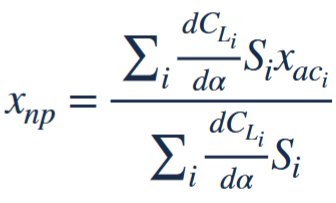

#### Lift Curve Slopes

LCS_MW = 0.1; %main wing lift curve slope CHANGE
LCS_HT = 0.1; %horizontal tail lift curve slope CHANGE
LCS_VT = 0.1; %vertical tail lift curve slope CHANGE

#### Neutral Point

NP_Overall = (LCS_MW*S*AC_G_MW + LCS_HT*S_HT*AC_G_HT + LCS_VT*S_VT*AC_G_VT)/(LCS_MW*S + LCS_HT*S_HT + LCS_VT*S_VT); %neutral point

Report as a percent of MAC

NP = (NP_Overall-L_MW)/c;

## Stability Analysis

SM = (NP_Overall - CG_Overall)/c; %static margin

## Plot

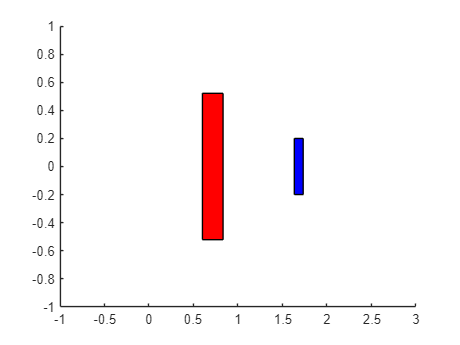

figure()
hold on
rectangle('Position',[L_MW*AL, -b/2, c, b],'FaceColor','r')
rectangle('Position',[CG_G_HT-(c_HT/4), -b_HT/2, c_HT, b_HT],'FaceColor','b')
xlim([-1,3])
ylim([-1, 1])